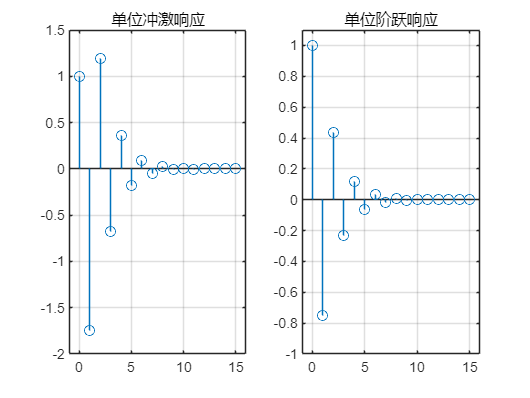

%y[n]+0.75y[n−1]+0.125y[n−2]=x[n]−x[n−1]
a = [1 0.75 0.125]; %差分方程左侧的系数
b = [1 -1]; %差分方程右侧的系数
n1 = 0:15; %定义时间向量n1，从0到15
hn1 = impz(b,a,n1); %计算单位冲激响应hn1
gn1 = stepz(b,a,n1); %计算单位阶跃响应gn1
figure(1)
subplot(1,2,1),stem(n1,hn1); %在第一个子图中绘制单位冲激响应
axis([-1 16 -2 1.5])
grid on; %显示网格线
title('单位冲激响应'); %将所绘图像命名为单位冲激响应
subplot(1,2,2),stem(n1,gn1); %在第二个子图中绘制单位阶跃响应
axis([-1 16 -1 1.1])
grid on; %显示网格线
title('单位阶跃响应'); %将所绘图像命名为单位阶跃响应

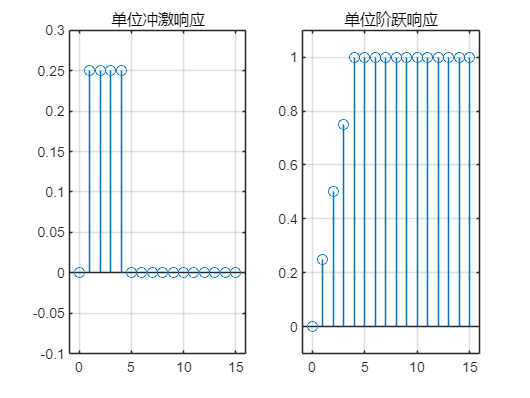


%y[n]=0.25{x[n−1]+x[n−2]+x[n−3]+x[n−4]}
a = [1]; %差分方程左侧的系数
b = [0 0.25 0.25 0.25 0.25]; %差分方程右侧的系数
n2 = 0:15; %定义时间向量n2，从0到15
hn2 = impz(b, a, n2); %计算单位冲激响应hn
gn2 = stepz(b, a, n2); %计算单位阶跃响应gn
figure(2)
subplot(1,2,1),stem(n1,hn2); %在第一个子图中绘制单位冲激响应
axis([-1 16 -0.1 0.3])
grid on; %显示网格线
title('单位冲激响应'); %将所绘图像命名为单位冲激响应
subplot(1,2,2),stem(n1,gn2); %在第二个子图中绘制单位阶跃响应
axis([-1 16 -0.1 1.1])
grid on; %显示网格线
title('单位阶跃响应'); %将所绘图像命名为单位阶跃响应